# **Calculate Correlations and Plot Bfactor**

clc; clear;
AA = load('HES.dat');
% Read as a sparse matrix
cont_sparse = sparse(AA(:,1), AA(:,2), AA(:,3));

% Combine upper and lower triangle
cont_sym = (cont_sparse + cont_sparse')/2;
% Halve the diagonal values
cont_sym(1:size(cont_sparse,1)+1:end) = cont_sym(1:size(cont_sparse,1)+1:end)/2;

% Convert to full matrix
cont = full(cont_sym);

## Extract coordinates and experimental B-factors from new_coords.pdb

fname = fopen('new_coords.pdb','r');
formatSpec = '%6s%5d%4s%4s%1s%4d%8.3f%8.3f%8.3f%4d%8.2f%3s';
A = textscan(fname, formatSpec);
fclose(fname);

x  = A{7};   % x coordinates
Bexp = A{11};% Experimental B-factors

resnum = length(x); % Number of residues (or atoms)

## Eigen Decomposition of the Hessian

%Assign Hessian to cont(:,:)

for i=1:length(AA(:,1))
    cont(AA(i,1),AA(i,2))=AA(i,3);
    cont(AA(i,2),AA(i,1))=AA(i,3);
end   

## Full Decomposition      

[U,S,V]=eig(cont);
w=diag(S(:,:));
U1=U(:,7:10);

## Mean Square Fluctutations (msf)

invcont=zeros(resnum*3);
for k = 7 : resnum*3
    for j = 1 :resnum*3
        for i= 1: resnum*3
            invcont(i,j)= invcont(i,j)+U(i,k)*V(j,k)/w(k);
        end
    end
end

msf=zeros(resnum,1);
for i=1:resnum
    msf(i,1)=invcont(3*i-2,3*i-2)+invcont(3*i-1,3*i-1)+invcont(3*i,3*i);
end

for i=1:resnum
    msf(i,1)=msf(i,1)/sqrt(mwt(i));
end

## Pearson Correlation

% Mean values
mbth = mean(Bth);
mbexp = mean(Bexp);

% Pearson correlation calculation
numerator = sum((Bexp - mbexp) .* (Bth - mbth));
denominator = sqrt(sum((Bexp - mbexp).^2) * sum((Bth - mbth).^2));
bcc_pearson = numerator / denominator;

## Plot b-factors

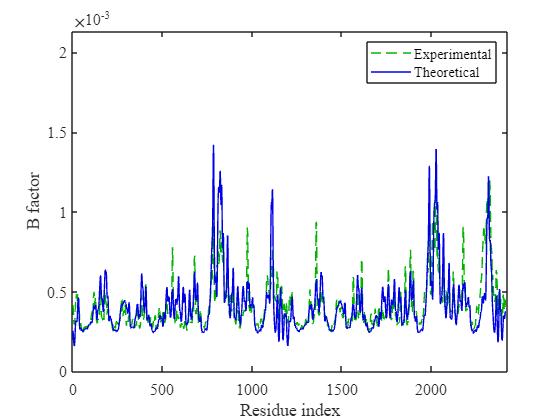

%plot b-fac.s
Exp = smoothdata(Bexp/sum(Bexp));
Th = smoothdata(Bth/sum(Bth),"gaussian");
Exp = str2double(string(Exp));
Th = str2double(string(Th));
fig=plot(1:resnum,Exp,'--',1:resnum,Th,'-');
fig(2).Color = [0 0 0.90];
fig(1).Color = [0 0.7 0];
xlim([0 1114]);
ylim([0.0000 0.0100]);
xlabel('Residue index');
ylabel('B factor');
legend('Experimental','Theoretical');
set(gca, 'FontName', 'times','FontSize',12)
% Calculate the maximum value of your x-axis data (resnum)
max_x_value = max(resnum);

% Calculate a slightly higher x-axis limit
x_axis_limit = max_x_value + 10; % You can adjust this increment as needed

% Calculate the maximum value of your y-axis data (Exp and Th)
max_y_value = max(max([Exp, Th]));

% Calculate a slightly higher y-axis limit
y_axis_limit = max_y_value + 0.001 * max_y_value; % You can adjust the multiplier as needed

% Set the x-axis and y-axis limits
xlim([0, x_axis_limit]);
ylim([0, y_axis_limit*1.5]);

saveas(gcf,'Bfacs.png');